## fv0 Intro

This scrip import expomential fitness as experiment data, and simulation result comes from GLE model with potential=0.5*psi*x^2

This scrip just changing para by hand and make the frame of simulation.

## GLENII fv0 Intro

change FDE into GLENII

## fv5 Intro

In order to plot fixed data, i adjust the detail of scrip to make it run smoothly.

## Import data and previewing

The data come from expomential fitness data.

data_name='n142';
selecting_curve='xy average';

load(['C:\Users\zhouquan\OneDrive\research\scrips\processed_data\mixed processed data ',data_name,'.mat'])

interceptive_experiment_MSD=1e-18*fun(a,time_scale);


## Parameter importing

kB=1.3806505e-23;
T=293;%confirmed

GLE_input=[2.63895324506976e-08,	2.00041767321758e-07,	0.710733048602047];

%m=GLE_input(1);
%psi=GLE_input(2);
mpsi=GLE_input(1);
zeta=GLE_input(2);
H=GLE_input(3);

## Main loop

simulation_MSD=[];
tau=((zeta*gamma(2*H+1))/mpsi)^(1/(2-2*H));
for t=experiment_interval*[1:min_length]
    simulation_MSD=[simulation_MSD,2*kB*T/mpsi-2*kB*T/mpsi*mlf(2-2*H,1,-(t/tau)^(2-2*H),8)];
end
residual=sum((interceptive_experiment_MSD-simulation_MSD).^2);

## Plot and saving

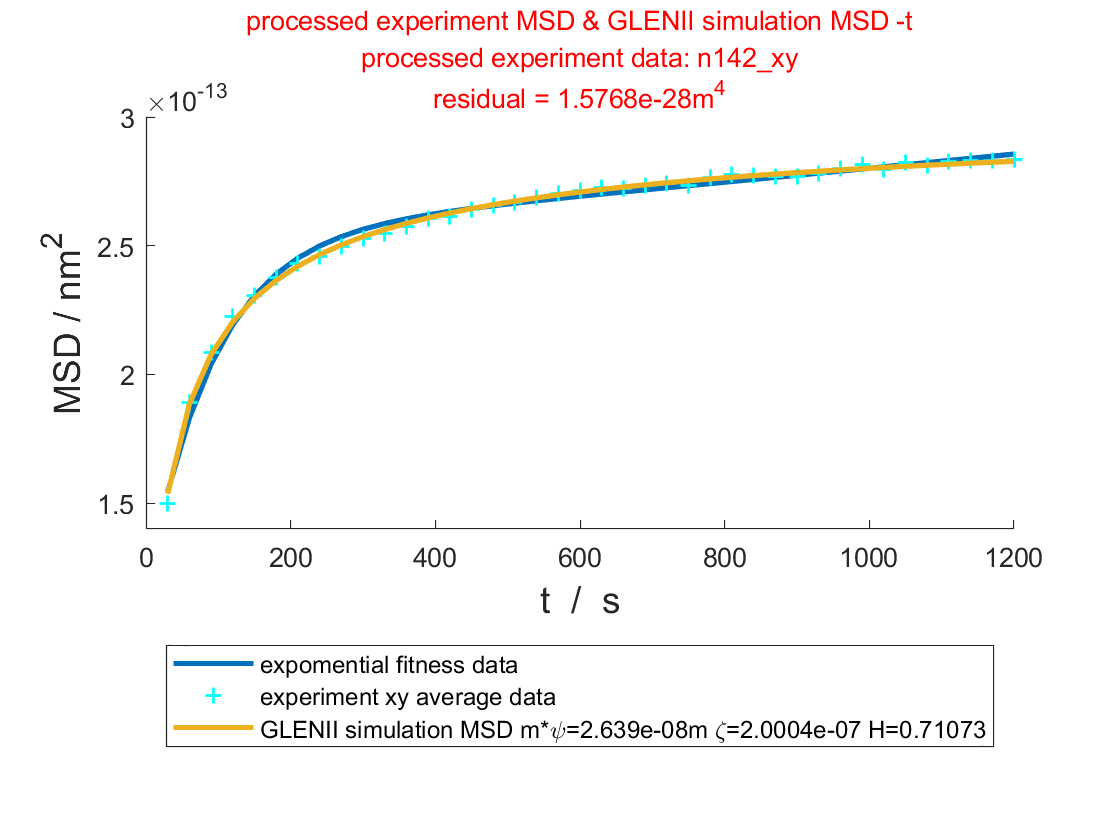

figure
hold on
plot(time_scale,interceptive_experiment_MSD,"LineWidth",2,'displayname','expomential fitness data')
plot(time_scale,1e-18*processed_MSD(1:min_length),'+',"DisplayName",'experiment xy average data',"Color",'cyan',"LineWidth",1)
legend_name=strcat('GLENII simulation MSD',' m*\psi= ',num2str(mpsi),'m \zeta=',num2str(zeta),' H= ',num2str(H));
plot(time_scale,simulation_MSD,"LineWidth",2,'displayname',legend_name)
xlabel('t  /  s','FontSize',14);
ylabel('MSD / nm^2','FontSize',14);
title({['processed experiment MSD & GLENII simulation MSD -t'],['processed experiment data: ',strrep(data_name,'_','\_'),'\_',selecting_curve],['residual = ',num2str(residual),'m^4']},'Color','r','FontSize',10);
legend('Location','southoutside');

## Saving

storage_location='C:\Users\zhouquan\OneDrive\research\DNA随机游走模拟\阶段报告2022.04图像';
c=clock;
%saveas(gcf,strrep([storage_location,'\image\GLE-MSD ',data_name,'_',num2str(experiment_interval),'s ',num2str(c(1)),'.',num2str(c(2)),'.',num2str(c(3)),' ',num2str(c(4)),num2str(c(5)),'.jpg'],'       ',' '))
